%zad 2 (z ograniczeniami)
clear

x0 = [1,10,10,1];

fun = @ident;
nonlinfcn = @Hurwitz;
%opts = optimoptions(@fmincon,'Algorithm','sqp');
opts = optimoptions(@fmincon,'Display','iter','Algorithm','sqp');
opts = optimoptions('fmincon','Display','iter','Algorithm','sqp');
%x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)
x = fmincon(fun,x0,[],[],[],[],[],[],nonlinfcn,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    1.201298e+02     2.220e-07     1.000e+00     0.000e+00     4.272e+01  
    1          12    1.069487e+02     1.829e-07     4.900e-01     5.074e+00     4.282e+02  
    2          19    7.514350e+01     1.478e-07     4.900e-01     3.632e+00     4.345e+01  
Objective function returned NaN; trying a new point...
    3          28    6.161446e+01     1.319e-07     2.401e-01     2.500e+00     1.094e+02  
    4          33    7.417177e+02     2.581e-08     1.000e+00     1.956e+02     2.682e+02  
    5          38    8.593032e+02     1.768e-08     1.000e+00     1.309e+02     1.346e+01  
    6          70    8.593032e+02     1.768e-08     1.104e-05     2.713e-04     1.346e+01  

Local minimum possible. Constraints

x =   294.4182  148.4760   59.2756    6.6829



G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                                     
          -s^3 + 24 s^2 - 240 s + 960
                                     
  -------------------------------------------
                                             
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3        
                                             
                   + 2490 s^2 + 2460 s + 1200
                                             
 
Continuous-time transfer function.



G2=tf([0 1.25],[x(1) x(2) x(3) x(4)]) % dla  %c = []

G2 =
 
                   1.25
  ---------------------------------------
  294.4 s^3 + 148.5 s^2 + 59.28 s + 6.683
 
Continuous-time transfer function.



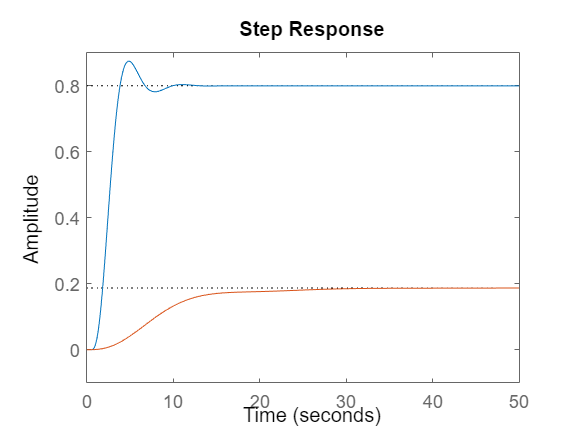

%G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])  % dla  c ;
step(G1,G2);


b=G2.Numerator{1, 1}

b =          0         0         0    1.2500


a=G2.Denominator{1,1}

a =   294.4182  148.4760   59.2756    6.6829


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.1751 + 0.3416i
  -0.1751 - 0.3416i
  -0.1540 + 0.0000i


k = 0.0042

x0 = [25.6106   42.2065    6.3499    1.9522]

x0 =    25.6106   42.2065    6.3499    1.9522



x = fmincon(fun,x0,[],[],[],[],[],[],nonlinfcn,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    2.275872e+02     7.394e-08     1.000e+00     0.000e+00     7.978e+01  
    1          13    2.188146e+02     1.019e-07     3.430e-01     8.506e-01     1.181e+02  
    2          18    1.791423e+02     1.270e-07     1.000e+00     5.369e+00     2.879e+01  
    3          23    1.746717e+02     9.695e-08     1.000e+00     2.282e+00     4.092e+00  
    4          28    1.561187e+02     1.798e-07     1.000e+00     2.814e+01     2.342e+02  
    5          33    1.455699e+02     9.613e-08     1.000e+00     9.994e+00     5.064e+01  
    6          56    1.456602e+02     9.609e-08     1.628e-03     3.294e-02     5.054e+01  
    7          97    1.456602e+02     9.609e-08     4.457e-07     1.203e-05     3.256e+00  



x =    14.4964   22.3448    7.4530    1.4259



G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 1.25],[x(1) x(2) x(3) x(4)]) % dla  %c = []

G2 =
 
                   1.25
  --------------------------------------
  14.5 s^3 + 22.34 s^2 + 7.453 s + 1.426
 
Continuous-time transfer function.



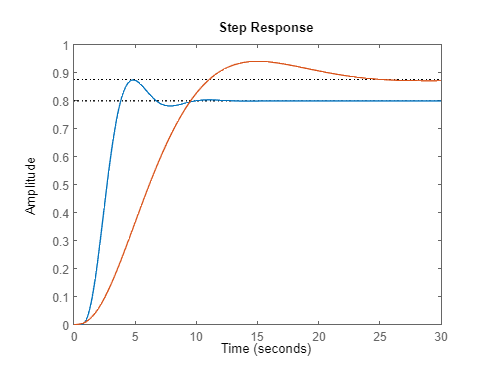

%G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])  % dla  c ;
step(G1,G2);


b=G2.Numerator{1, 1}

b =          0         0         0    1.2500


a=G2.Denominator{1,1}

a =    14.4964   22.3448    7.4530    1.4259


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -1.1751 + 0.0000i
  -0.1831 + 0.2240i
  -0.1831 - 0.2240i


k = 0.0862

x0 = [0.62,10,10,1]

x0 =     0.6200   10.0000   10.0000    1.0000



x = fmincon(fun,x0,[],[],[],[],[],[],nonlinfcn,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    1.202811e+02     2.833e-07     1.000e+00     0.000e+00     4.299e+01  
    1          12    1.145941e+02     2.202e-07     4.900e-01     4.982e+00     4.636e+02  
    2          19    5.977366e+01     1.688e-07     4.900e-01     2.830e+00     3.126e+01  
    3          28    5.334581e+01     1.619e-07     2.401e-01     3.050e+00     8.700e+01  
    4          33    2.375104e+01     1.653e-07     1.000e+00     7.550e+00     6.332e+01  
    5          43    2.355052e+01     1.522e-07     1.681e-01     8.376e-01     4.321e+01  
    6          50    9.488374e+01     1.157e-07     4.900e-01     1.379e+01     7.396e+01  
Objective function returned NaN; trying a new point...
    7          57    1.723240e+02     1.047e-07     4.900e-01     9.967e+00     1.788e+02  
    8          62    4.2941

x =    11.0266    8.7586    7.2098    1.8191



G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 1.25],[x(1) x(2) x(3) x(4)]) % dla  %c = []

G2 =
 
                   1.25
  --------------------------------------
  11.03 s^3 + 8.759 s^2 + 7.21 s + 1.819
 
Continuous-time transfer function.



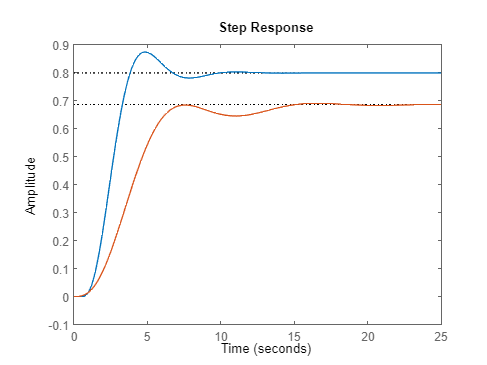

%G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])  % dla  c ;
step(G1,G2);


b=G2.Numerator{1, 1}

b =          0         0         0    1.2500


a=G2.Denominator{1,1}

a =    11.0266    8.7586    7.2098    1.8191


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.2324 + 0.6683i
  -0.2324 - 0.6683i
  -0.3295 + 0.0000i


k = 0.1134

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    9.016618e+02     5.486e-07     1.000e+00     0.000e+00     6.182e+03  
    1          14    5.247753e+02     5.371e-07     2.401e-01     1.273e+00     1.483e+03  
    2          19    1.594154e+02     3.424e+00     1.000e+00     3.127e+00     2.157e+16  
Objective function returned NaN; trying a new point...
    3          28    6.065544e+01     2.677e+00     2.401e-01     2.401e+00     1.150e+16  
Objective function returned NaN; trying a new point...
    4          36    4.966428e+01     2.016e+00     3.430e-01     1.425e+00     3.437e+15  
    5          47    2.740613e+01     1.815e+00     1.176e-01     1.593e-01     1.971e+15  
    6          59    2.279991e+01     1.680e+00     8.235e-02     9.032e-02     1.929e+15  
    7          72    2.003761e+01     1.589e+00     5.765e-02   

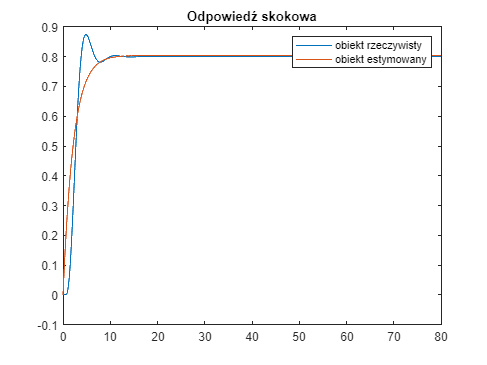

Objective function returned NaN; trying a new point...
   10         146    1.871279e+01     1.342e+00     6.571e-05     9.855e-07     1.108e+15  

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0000    0.0000    2.7241    1.2431


x0 = [1,2,1.01,0.9];
x = fmincon(fun,x0,[],[],[],[],[],[],nonlinfcn,opts)


G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 1.25],[x(1) x(2) x(3) x(4)]) % dla  %c = []

G2 =
 
                       1.25
  -----------------------------------------------
  7.298e-07 s^3 + 3.655e-07 s^2 + 2.724 s + 1.243
 
Continuous-time transfer function.



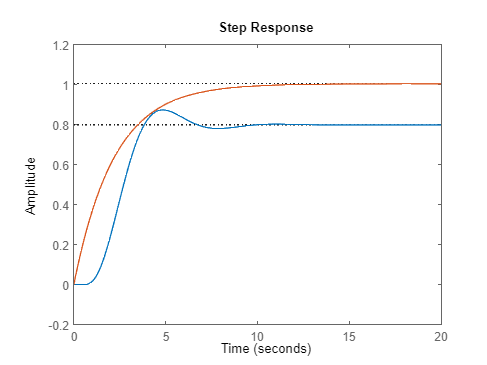

%G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])  % dla  c ;
step(G1,G2);


b=G2.Numerator{1, 1}

b =          0         0         0    1.2500


a=G2.Denominator{1,1}

a =     0.0000    0.0000    2.7241    1.2431


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p = 	1.0e+03 *

  -0.0000 + 1.9321i
  -0.0000 - 1.9321i
  -0.0005 + 0.0000i


k = 1.7129e+06

function [c,ceq] = Hurwitz(x)
%Kryt Hurwitza
H=[x(2) x(4)  0;x(1) x(3) 0;0 x(2) x(4)];
H1=H(1,1);
H2=H(1:2,1:2);
a0=x(4);
a1=x(3);
a2=x(2);
a3=x(1);
Det_H1=det(H1);
Det_H2=det(H2);
Det_H=det(H);

mian_p=0.0000001; % wsp korygujacy NaN dzielenie przez zero;
c5=abs(Det_H2)/(Det_H2+mian_p);
c6=abs(Det_H)/(Det_H+mian_p);

a0_abs=abs(x(4))/(x(4)+mian_p);
a1_abs=abs(x(3))/(x(3)+mian_p);
a2_abs=abs(x(2))/(x(2)+mian_p);
a3_abs=abs(x(1))/(x(1)+mian_p);

c(1) = -x(1);
c(2) = -x(2);
c(3) = -x(3);
c(4) = -x(4);
%c(5) = c5 - 1;
%c(6) = c6 - 1;

c(5) = -Det_H2;
c(6) = -Det_H;

%c = []; % wylaczenie  nierownosci
ceq=a0_abs+a1_abs+a2_abs+a3_abs+c5+c6-6;

end

function blad = ident(x)
%K = X0(1);
%T = X0(2);
%n = X0(3);

%a1=x(1);
%b2=x(2);

t=0:0.01:20;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;

G2=tf([0 1],[x(1) x(2) x(3) x(4)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie

e = y1-y2;
blad= sum(e.^2);
%blad= sum(e.^2) / length(e);
end